# Secant Method in Calculating Nonlinear Equation

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

There are several methods to solve a Nonlinear equation. based on the answer range and the form of equation, continuty, and asceding or desceding of the objective function, each method can be used! 

One of the useful methods is Secant Method. In the first glance, it is very similar to False-Position Method, but there is a fundamental difference between these methods. Despite of False-Position Method, this method just needs two first initial guesses (These guesses should not have a large difference). 

Subject to the convergence of calculations, this method is faster than False-Position method! 

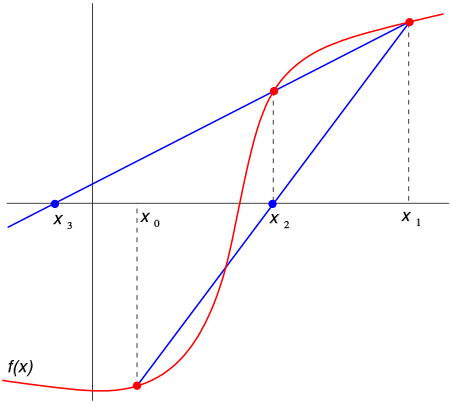

*The first two iterations of the secant method. The red curve shows the function f, and the blue lines are the secants. For this particular case, the secant method will not converge to the visible root. - *[*Source*](https://en.wikipedia.org/wiki/Secant_method) 

### Part1: Input data

clear, clc
syms x
f = input('Enter the equation:');
init_guess = input('Enter the initial guess as a vector [xi-1, xi]: ');
desired_err = 0.001;
max_iterations = 100; % Limit the maximum number of iterations

prev_xr = init_guess(1);
curr_xr = init_guess(2);

### Part2: Root Calculation

In this part, the root of the equation should be calculated using the following equation (Assume that the equation is wrote in the form of $f\left(x\right)=0$):


$$x_r =x_i -\frac{\left(f\left(x\right)\times \left(x_{i-1} -x_i \right)\right)}{f\left(x_{i-1} \right)-f\left(x_i \right)}$$


for i = 1:max_iterations
    next_xr = curr_xr - (subs(f, x, curr_xr) * (curr_xr - prev_xr)) / ...
              (subs(f, x, curr_xr) - subs(f, x, prev_xr));
          
    % Check for convergence
    if abs(next_xr - curr_xr) < desired_err
        break
    end
    
    % Update values for the next iteration
    prev_xr = curr_xr;
    curr_xr = next_xr;
end
disp('The root of equation is: '), disp(double(xr))